Definicja dynamiki układu:


$$\dot{x} =\textrm{Ax}$$


a11 = -2;
a12 = 0;
a21 = -5;
a22 = -8;
A = [a11 a12; a21 a22];
A_sym = sym(A);

disp("Oryginalna macierz układu:");

Oryginalna macierz układu:


disp(A_sym);

$$\left(\begin{array}{cc} -2 & 0\\ -5 & -8 \end{array}\right)$$

Wyznaczamy wartości własne macierzy $A$

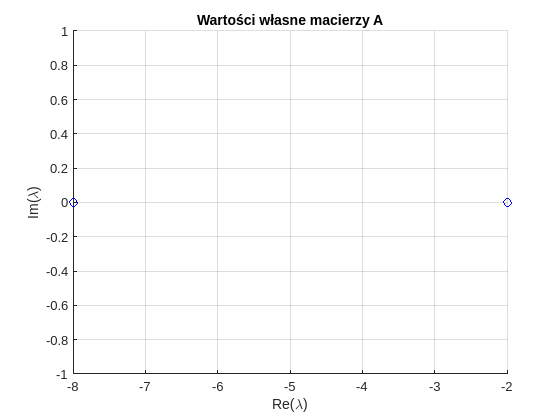

[~, lambda] = eig(A);

figure();
grid on;
hold on;
xlabel("Re(\lambda)");
ylabel("Im(\lambda)");
title("Wartości własne macierzy A");
for index = 1:size(lambda, 1)
    l = lambda(index, index);
    plot(real(l), imag(l), "bo");
end

Wyznaczenie pstaci kanonicznej Jordana:

% Obliczenie postaci Jordana J oraz macierzy przejścia V
[V, J] = jordan(A_sym);

disp('Postać Jordana J:');

Postać Jordana J:


disp(J);

$$\left(\begin{array}{cc} -8 & 0\\ 0 & -2 \end{array}\right)$$

Wyznaczenie postaci kanonicznej Frobeniusa:

% 1. Znalezienie współczynników wielomianu charakterystycznego
p = charpoly(A_sym); % współczynniki: s^n + a_{n-1}s^{n-1} + ... + a_0

% 2. Uzyskanie macierzy towarzyszącej (postać Frobeniusa)
% MATLAB-owa funkcja compan(p) tworzy postać z jedynkami pod nadprzekątną
C = compan(p);
F = flip(flip(C,1),2);

disp('Macierz w postaci Frobeniusa:');

Macierz w postaci Frobeniusa:


disp(F);

$$\left(\begin{array}{cc} 0 & 1\\ -16 & -10 \end{array}\right)$$

Wyrysownie portretów dynamiki dla każdej postaci:

- Wyjściowa

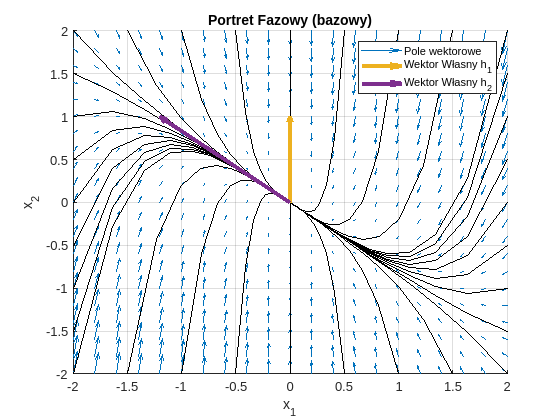

PlotPhasePortrait(A, V, true, "bazowy");

- Jordana

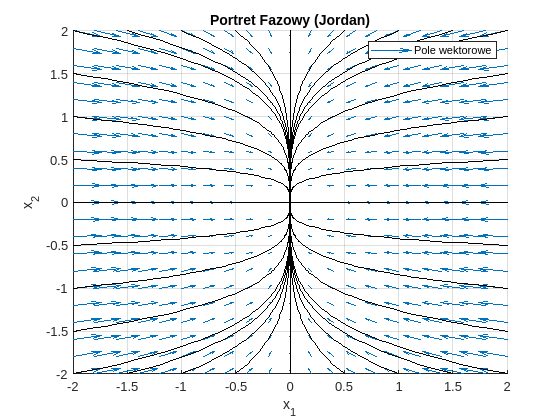

PlotPhasePortrait(double(J), [], false, "Jordan");

- Frobeniusa

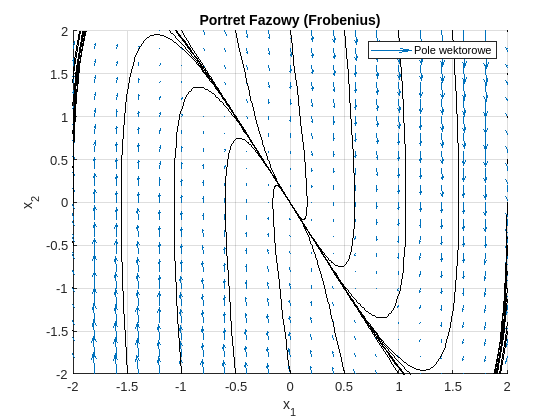

PlotPhasePortrait(double(F), [], false, "Frobenius");

Funkcje pomocnicze:

function PlotPhasePortrait(A, h, plot_h, name)
    [X1, X2] = meshgrid(-2:0.2:2);
    dX1 = A(1, 1) * X1 + A(1, 2) * X2;
    dX2 = A(2, 1) * X1 + A(2, 2) * X2;
    
    figure();
    grid on;
    hold on;
    xlabel("x_1");
    ylabel("x_2");
    title("Portret Fazowy (" + name + ")");
    xlim([-2, 2]);
    ylim([-2, 2]);
    legend("show");
    
    % Rysuj pole wktorowe
    quiver(X1, X2, dX1, dX2, 1, "DisplayName", "Pole wektorowe");
    
    % Rysuj przykładowe trajektorie
    X0 = {[-2;2], [-1.5;2], [-1;2], [-0.5;2], [0;2], [0.5;2], [1;2], [1.5;2], [2;2], ...
        [-2;-2], [-1.5;-2], [-1;-2], [-0.5;-2], [0;-2], [0.5;-2], [1;-2], [1.5;-2], [2;-2], ...
        [-2;-2], [-2;-1.5], [-2;-1], [-2;-0.5], [-2;0], [-2;0.5], [-2;1], [-2;1.5], [-2;2], ...
        [2;-2], [2;-1.5], [2;-1], [2;-0.5], [2;0], [2;0.5], [2;1], [2;1.5], [2;2]};
    for index = 1:length(X0)
        x0 = X0{index};
        [~, y] = ode45(@(t, x)A*x,0:0.01:100, x0);
        plot(y(:, 1),y(:, 2), "k", "HandleVisibility", "off");
    end
    
    % Rysuj wektory własne
    if plot_h
        for index = 1:size(h, 1)
            hi = h(:, index);
            quiver(0, 0, real(hi(1)), real(hi(2)), 1, "LineWidth", 3, "DisplayName", "Wektor Własny h_"+index);
        end
    end
end